# Miniprojekt 2 - Fkrevensanalyse af målte vibrationssignaler

## Indledning

## 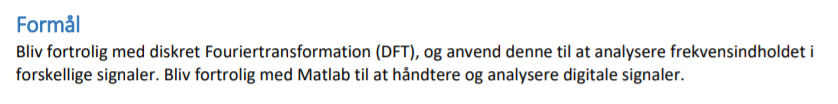

## Loading af fil

VI vil starte med at loade signalet ind i Matlab sammen med dens samplingfrekvens.

load("Opgave2_audiofil_1_1.mat");

## Plot af signal

Først laves den korrekte skalering af amplituden, da 1 volt svarer til 100 enheder.

raw_input = raw_input.*0.01;

Først beregnes sample periode tiden med formlen:


$$\mathrm{Ts}=\frac{1}{\mathrm{Fs}}$$


fs

Nu da vi har loaded signalet ind, kan vi starte med at plotte de første fem sekunder.

Ts=1/fs

Ts = 3.9063e-05

Nu laves en tidsakse på fem sekunder:

t=0:Ts:5;

Et array over alle elemneter laves:

n=0:length(raw_input)-1;

Signalet kan nu plottes:

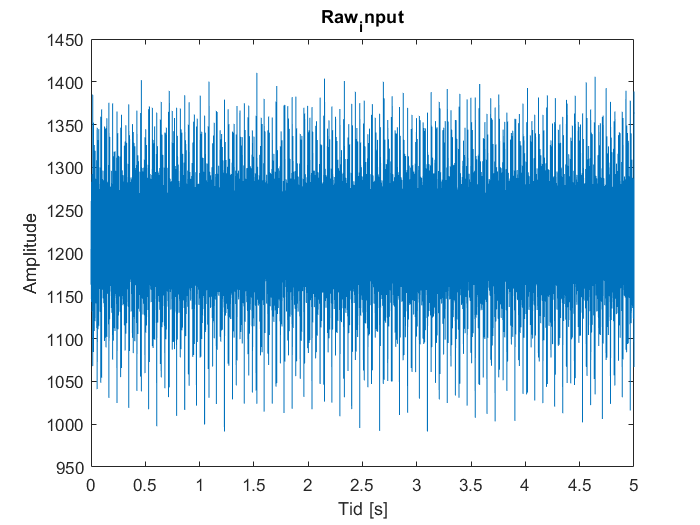

fs = 25600

plot(n*Ts,raw_input)
title('Raw_input')
xlabel('Tid [s]')
ylabel('Amplitude')
xlim([0 5])
%ylim([(min(raw_input)*1.2) (max(raw_input)*0.8)])
hold off

N = length(raw_input) % Antal samples

N = 262144


t_5 = t<=5 ;
raw_input5 = raw_input(t_5);
soundsc(raw_input5,fs); % Afspilning af raw_file
mid = myMean(raw_input5) % Middelværdien

mid = 12.1765

rms = myRMS(raw_input5) % RMS-værdien

rms = 12.1809

energi = myEnergy(raw_input5) % Energien

energi = 1.8992e+07